# Eclipse 🌑🌒🌓

Analyze the total solar eclipse

2024-04-08

## Context

In this tutorial, we will show how to use MATLAB with the SunPy community Python library for Solar Physics

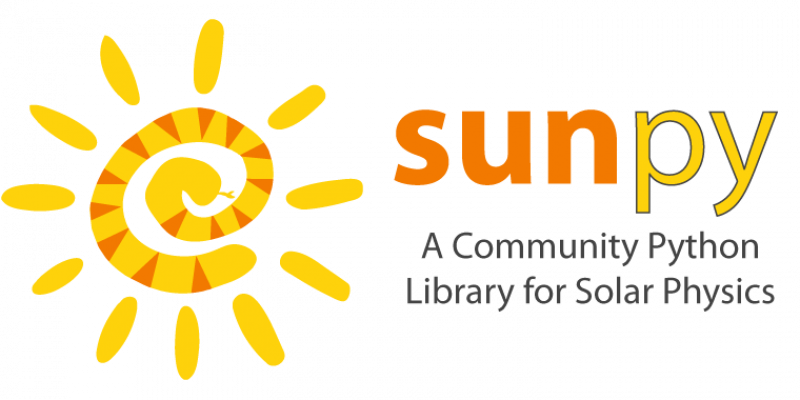

## Resources

- [https://github.com/yanndebray/matlab-with-python-book](https://github.com/yanndebray/matlab-with-python-book)

- [https://docs.sunpy.org/en/stable/generated/gallery/showcase/eclipse_amount.html](https://docs.sunpy.org/en/stable/generated/gallery/showcase/eclipse_amount.html) 

## Set up environment

setup

pip set up in folder: /tmp/
Defaulting to user installation because normal site-packages is not writeable
□[?25l     □━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━□ □0.0/60.9 kB□ □?□ eta □-:--:--□
□[2K     □━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━□ □60.9/60.9 kB□ □15.6 MB/s□ eta □0:00:00□
□[?25hCollecting packaging>=19.0 (from sunpy)
  

pipshow("numpy")

Name: numpy
Version: 2.0.0
Summary: Fundamental package for array computing in Python
Home-page: https://numpy.org
Author: Travis E. Oliphant et al.
Author-email: 
License: Copyright (c) 2005-2024, NumPy Developers.
        All rights reserved.
        
        Redistribution and use in source and binary forms, with or without
        modification, are permitted provided that the following conditions are
        met:
        
            * Redistributions of source code must retain the above copyright
               notice, this list of conditions and the following disclaimer.
        
            * Redistributions in binary form must reproduce the above
               copyright notice, this list of conditions and the following
               disclaimer in the documentation and/or other materials provided
               with the distribution.
        
            * Neither the name of the NumPy Developers nor the names of any
               contributors may be used to endorse or promot

## Import data with Python live task

pyrunfile("runpy.py")

pipinstall("scikit-learn")

Eclipse detected:
  Partial solar eclipse starts at 2024-04-08 17:15:00.000 UTC
  Total solar eclipse starts at 2024-04-08 18:33:44.000 UTC
  Total solar eclipse ends at 2024-04-08 18:35:34.000 UTC
  Partial solar eclipse ends at 2024-04-08 19:55:00.000 UTC


pipshow("scikit-learn")

Defaulting to user installation because normal site-packages is not writeable
□[?25l     □━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━□ □0.0/60.8 kB□ □?□ eta □-:--:--□
□[2K     □━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━□ □60.8/60.8 kB□ □10.3 MB/s□ eta □0:00:00□
□[?25hCollecting joblib>=1.2.0 (from scikit-learn)

pipinstall("scipy")

Name: scikit-learn
Version: 1.5.1
Summary: A set of python modules for machine learning and data mining
Home-page: https://scikit-learn.org
Author: 
Author-email: 
License: new BSD
Location: /home/matlab/.local/lib/python3.10/site-packages
Requires: joblib, numpy, scipy, threadpoolctl
Required-by: 


## Transform Pandas Dataframe to MATLAB Table

% T = table(df)
TT = timetable(df)

Defaulting to user installation because normal site-packages is not writeable


% stackedplot(TT)
plot(TT.time,TT.amount)

TT = 831x2 timetable
            time            amount    amount_minimum
    ____________________    ______    ______________

    08-Apr-2024 16:35:00      0             0       
    08-Apr-2024 16:36:00      0             0       
    08-Apr-2024 16:37:00      0             0       
    08-Apr-2024 16:38:00      0             0       
    08-Apr-2024 16:39:00      0             0       
    08-Apr-2024 16:40:00      0             0       
    08-Apr-2024 16:41:00      0             0       
    08-Apr-2024 16:42:00      0             0       
    08-Apr-2024 16:43:00      0             0       
    08-Apr-2024 16:44:00      0             0       
    08-Apr-2024 16:45:00      0             0       


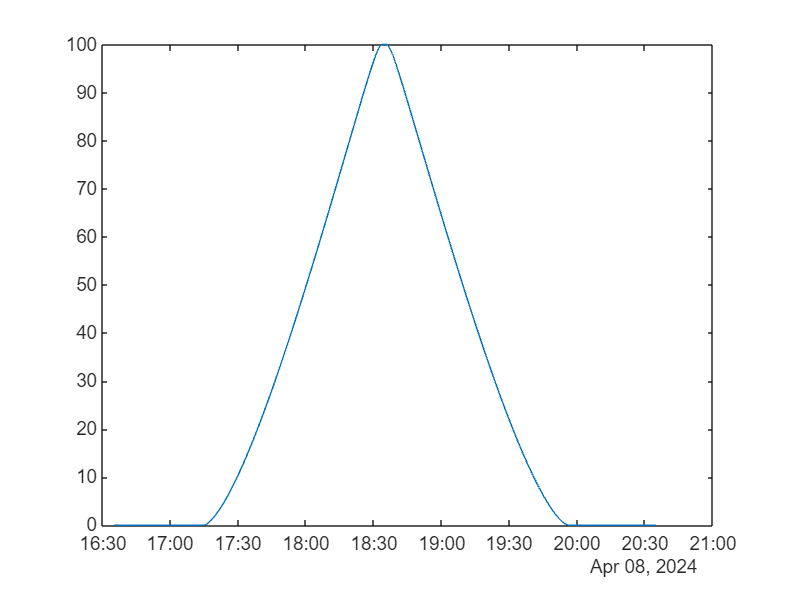

% San Antonio, Texas
lat = py.numpy.array(latitude); lat = double(lat);

lon = py.numpy.array(longitude); lon = double(lon);
geoscatter(lat,lon, 'filled')

## Export to ipynb and md

export('livescript.mlx','README.md');
export('livescript.mlx','notebook.ipynb');

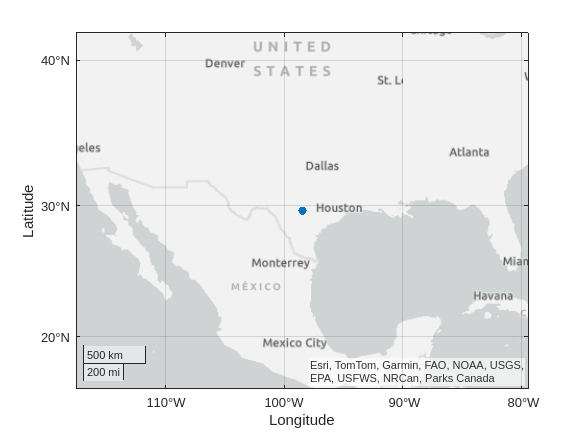

% Python code input

pycode = [...
"import numpy as np",...
" ",...
"# Define the corpus of text",...
"corpus = [",...
"    ""The quick brown fox jumped over the lazy dog."",",...
"    ""She sells seashells by the seashore."",",...
"    ""Peter Piper picked a peck of pickled peppers.""",...
"]",...
" ",...
"# Create a set of unique words in the corpus",...
"unique_words = set()",...
"for sentence in corpus:",...
"    for word in sentence.split():",...
"        unique_words.add(word.lower())",...
" ",...
"# Create a dictionary to map each",...
"# unique word to an index",...
"word_to_index = {}",...
"for i, word in enumerate(unique_words):",...
"    word_to_index[word] = i",...
" ",...
"# Create one-hot encoded vectors for",...
"# each word in the corpus",...
"one_hot_vectors = []",...
"for sentence in corpus:",...
"    sentence_vectors = []",...
"    for word in sentence.split():",...
"        vector = np.zeros(len(unique_words))",...
"        vector[word_to_index[word.lower()]] = 1",...
"        sentence_vectors.append(vector)",...
"    one_hot_vectors.append(sentence_vectors)",...
" ",...
"# Print the one-hot encoded vectors ",...
"# for the first sentence",...
"#print(""One-hot encoded vectors for the first sentence:"")",...
"#for vector in one_hot_vectors[0]:",...
"  #  print(vector)"...
];

try
    [corpus, unique_words, word_to_index, one_hot_vectors] = pyrun(pycode, ...
         [ "corpus" "unique_words" "word_to_index" "one_hot_vectors" ])
catch ME
    % Clear temporary variables from workspace and from Python
    clear pycode;
    rethrow(ME)
end

% Clear temporary variables from workspace and from Python
clear pycode;

cell(one_hot_vectors)